**Create color maps for each subset mxvi **

*Create colormap for entire map to be subsetted for individual scenes*

year_i =1;
cur_mxvi = double(mxvi_vals{year_i});
cur_mxvi = cur_mxvi / 10000;
ovr_mxvi = ones(m_r, m_c, "double");

*Apply the water mask to the mxvi matrix*

load 'ancillary_mat/modis_qkm_water_mask.mat' water1_land0;
% cur_mask = reshape(water1_land0, r, c);
for i = 1:r
    for j= 1:c
        cur_pxid = modis_qkm_pxid(i, j);
    
        if (water1_land0(cur_pxid) == 1) 
            ovr_mxvi(i, j) = nan;
        else
            ovr_mxvi(i, j) = cur_mxvi(cur_pxid);
        end
    end
end

temp_map = imshow(cur_mxvi, 'Colormap', parula);

save 'figs/ovr_mxvi.png' temp_map;
clearvars -regexp cur_;
clearvars water1_land0;

**Create colormaps for each scene and save them to the fig directory**

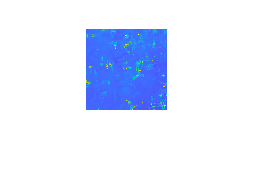

for scene_i = 1:m_scene_count
    cur_name = m_scene_names(scene_i);
    cur_f_name = append('figs/', cur_name, '_cmap.png');
    cur_f1_name = append('figs/', cur_name, '_cmap.fig');
    cur_kmz_name = append('figs/', cur_name, '.kmz');
    
    cur_mxvi_subset = mxvi_subset{year_i, scene_i}; 
    cur_cmap = imshow(cur_mxvi_subset, 'Colormap', parula);
    
    save([cur_f_name], 'cur_cmap');
    % save([cur_f1_name], 'cur_cmap');
    % export_overlay(cur_f_name, cur_kmz_name, pxid_matrices{2, scene_i});
end